%% Load data and visualize
addpath("routines\");

load("data/ecgpvc.mat");
% visualpvc(ecgpvc);

## Take five representative ectopic beats

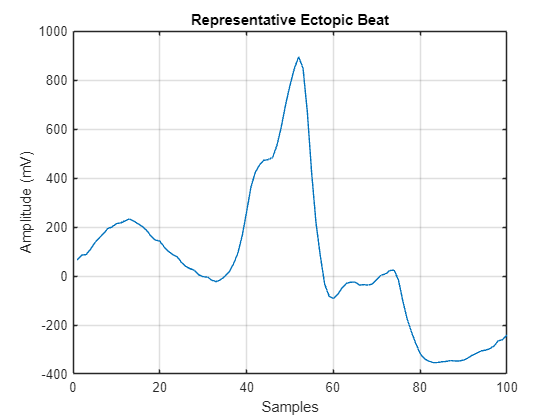

% Manually take the peaks
peaks = [39.25, 41.12, 45.39,47.345 ,49.1 ];
fs = 200;
peak_samples = peaks * fs;
sample_window = 50;

window_accum_values = zeros(sample_window*2, 1);
for i = peak_samples
    window = ecgpvc(i-sample_window:i+sample_window-1);
    window_accum_values = window_accum_values + window;
end

representative_beat = window_accum_values / length(peak_samples);

figure;
plot(representative_beat);
title('Representative Ectopic Beat');
xlabel('Samples')
ylabel('Amplitude (mV)')
grid on;

## Xcorr between ECG signal and Representative ectopic Beat

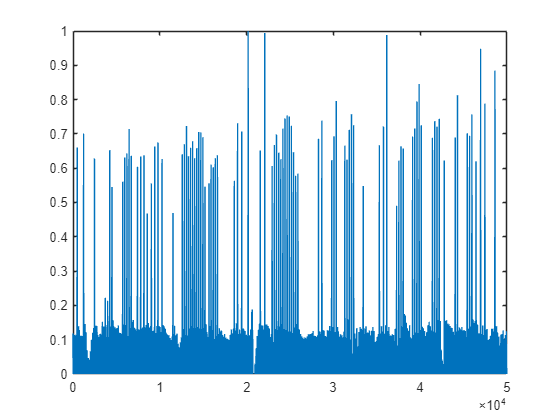

% Normalize signals

[corr, lags] = xcorr(ecgpvc, representative_beat);
trimmed_corr = corr(lags >= 0);

% Normalize corr
normalized_trim_corr = trimmed_corr / max(trimmed_corr);

figure()
plot(normalized_trim_corr);
ylim([0 1])

## Apply threshold 

## Islocalmax

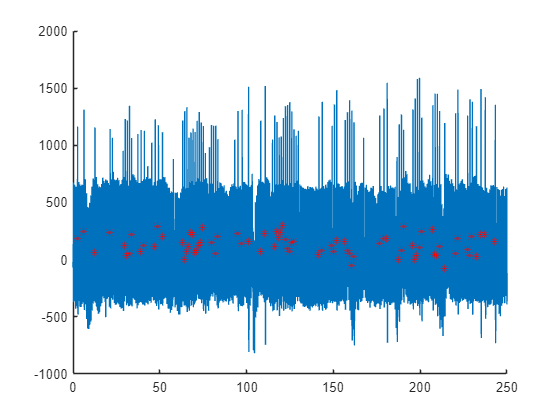


% Define the time
time = linspace(0, 250, 50000);

% Apply the threshold
threshold = 0.4;

% Find indxs above the threshold
idxs = find(normalized_trim_corr >= threshold);

% Find local maximum values of idxs
center_idx = find(islocalmax(normalized_trim_corr(idxs)) == 1);
max_samples = idxs(center_idx);
plot_local_max(ecgpvc, time, max_samples);

## findpeaks

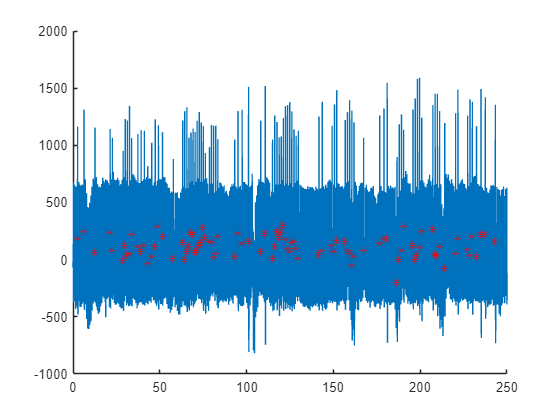

% Define the time
time = linspace(0, 250, 50000);

% Apply the threshold
threshold = 0.4;

% Find indxs above the threshold
[~, idxs] = findpeaks(normalized_trim_corr, "MinPeakHeight", 0.4);

plot_local_max(ecgpvc, time, idxs, 100);